% Calculate complexities for different quantisation levels, and load random string complexities
maxn = size(X,2); maxq = 5; chanum = 4; dt=1/fs; x= transpose(X(chanum, :));
c      = zeros(maxn,maxq);             % complexities of x
crnd   = zeros(maxn,maxq);             % random string complexities
qtiles = cell(maxq,1);                 % quantiles
for q = 1:maxq                         % for each quantisation
	fprintf('processing qauntisation %d of %d... ',q,maxq);
	d = q+1;                           % alphabet size = number of quantiles + 1
	[s,qtiles{q}] = LZc_quantise(x,q); % quantise noise sequence by q quantiles; store quantiles
	c(:,q) = LZc_x(s,d);               % calculate "running" LZ complexity (i.e., for all sequence lengths to maximum)
	crnd(:,q) = LZc_crand(1:maxn,d);   % load random string mean complexities from file
	fprintf('done\n');
end

processing qauntisation 1 of 5... 

done


processing qauntisation 2 of 5... 

done


processing qauntisation 3 of 5... 

done


processing qauntisation 4 of 5... 

done


processing qauntisation 5 of 5... 

done


cnorm = c./crnd;                       % complexities normalised by mean complexity of random strings of same length and alphabet size

n = (1:maxn)'; % sequence lengths
t = dt*(n-1);  % corresponding time stamps

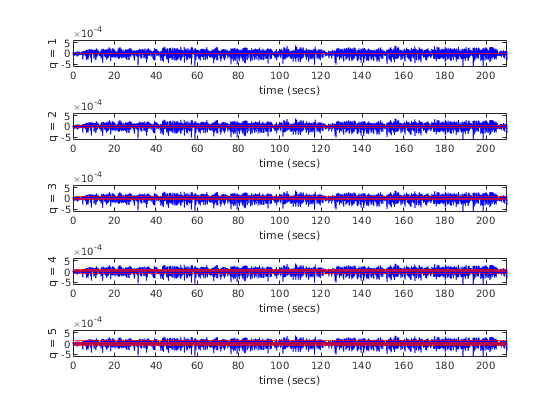

% Display time series with quantiles

figure(1); clf

xmax = 1.05*max(abs(x));
for q = 1:maxq
	subplot(maxq,1,q);
	plot(t,x);
	for k = 1:q
		yline(qtiles{q}(k),'color','r');
	end
	xlim([0,dt*maxn]);
	ylim([-xmax xmax]);
	xlabel('time (secs)');
	ylabel(sprintf('q = %d',q));
end

% sgtitle('Time series with quantisations'); % only version >= 2018b

% Estimate power spectral density of time series

[S,f] = pwelch(x,[],[],[],fs);         % estimated PSD (Welch method)
w = 2*pi*f/fs;                         % normalised frequency in [0,pi]

% Display PSD and normalised complexities

figure(2); clf

subplot(2,1,1);
semilogx(f,log((fs/2)*S));
xlim([f(2) fs/2]); % to Nyqvist frequency
title(sprintf('Power spectral density (f_s = %gHz)',fs));
legend('estimated','theoretical');

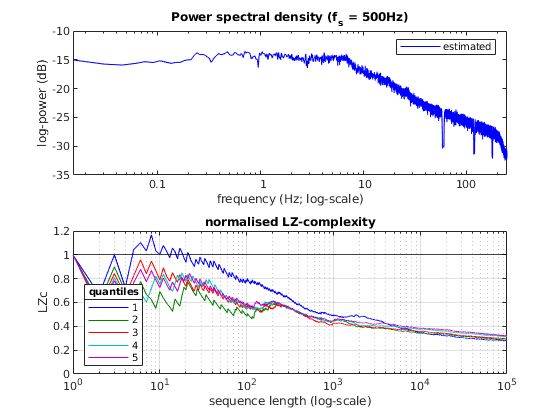

xlabel('frequency (Hz; log-scale)');
ylabel('log-power (dB)');
set(gca,'XTickLabel',num2str(get(gca,'XTick')')); % ridiculous faff to force sensible tick labels

subplot(2,1,2);
semilogx(n,cnorm);
ylim([0 1.2]);
yline(1,'color','k');
title('normalised LZ-complexity');
xlabel('sequence length (log-scale)');
ylabel('LZc');
leg = legend(num2str((1:maxq)','%2d'),'location','southwest');
leg.Title.Visible = 'on';
title(leg,'quantiles');
grid on